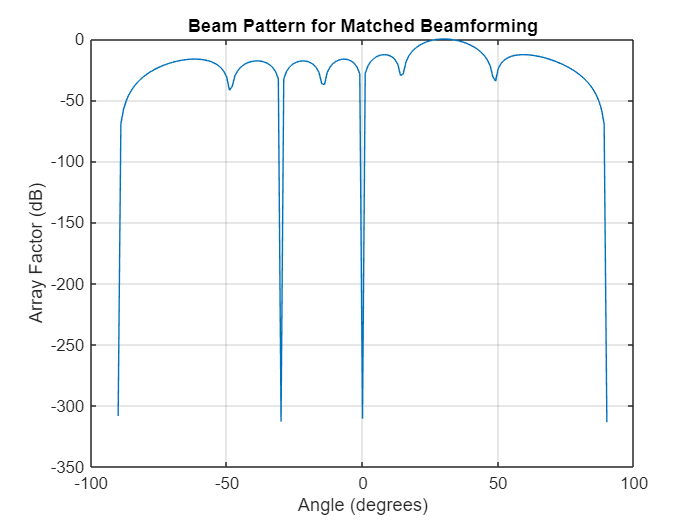

% Parameters
N = 8;               % Number of antennas
d = 0.5;             % Antenna spacing (in wavelengths)
theta_desired = 30;  % Desired Angle of Arrival (degrees)
theta_range = -90:1:90; % Angle range for visualization
lambda = 1;          % Wavelength
k = 2*pi/lambda;     % Wavenumber

% Steering vector for the desired AoA
theta_rad = deg2rad(theta_desired);
h = exp(-1j * k * d * (0:N-1)' * sin(theta_rad)); % Channel vector

% Matched beamforming weight vector
w = h / norm(h);

% Compute array factor
AF = zeros(size(theta_range));
for idx = 1:length(theta_range)
    phi = deg2rad(theta_range(idx));
    a_phi = exp(-1j * k * d * (0:N-1)' * sin(phi)); % Steering vector
    AF(idx) = abs(w' * a_phi); % Beamforming response
end

% Normalize and plot array factor
AF = AF / max(AF); % Normalize for visualization
figure;
plot(theta_range, 20*log10(AF)); % Plot in dB scale
xlabel('Angle (degrees)');
ylabel('Array Factor (dB)');
title('Beam Pattern for Matched Beamforming');
grid on;